clear;
handle = load("initial_data\initial_handle.mat");
seat = load("initial_data\initial_seat.mat");

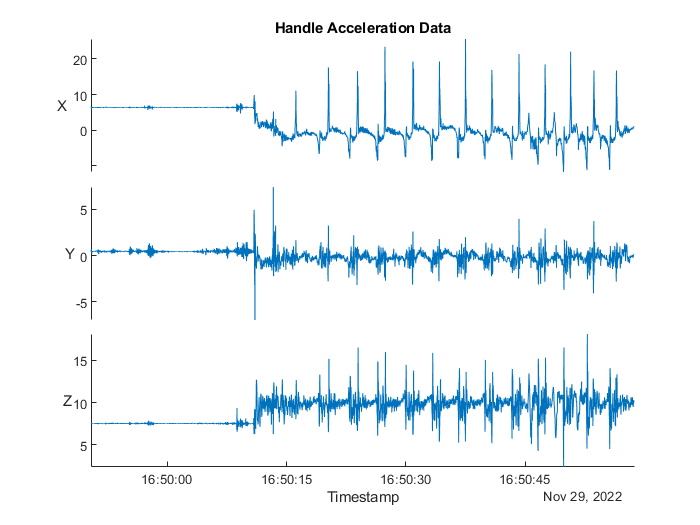

clf;
stackedplot(handle.Acceleration);
title("Handle Acceleration Data")

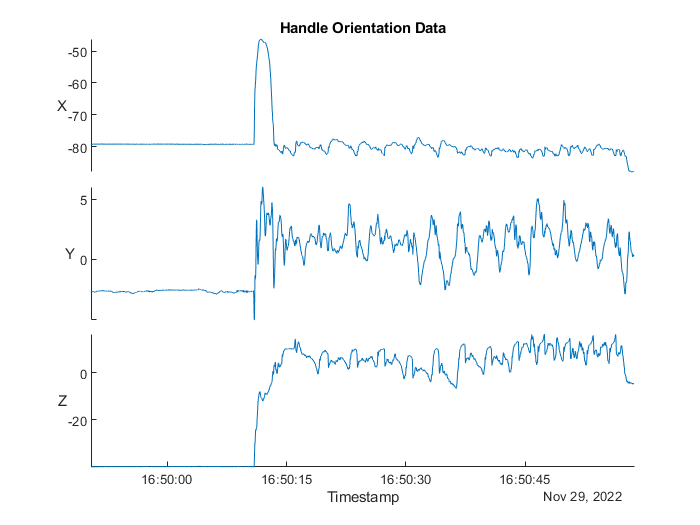


clf;
stackedplot(handle.Orientation);
title("Handle Orientation Data")

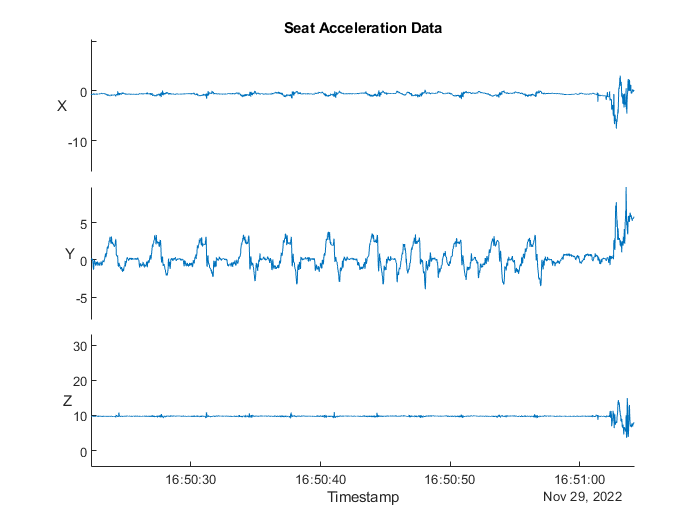


clf;
stackedplot(seat.Acceleration);
title("Seat Acceleration Data")

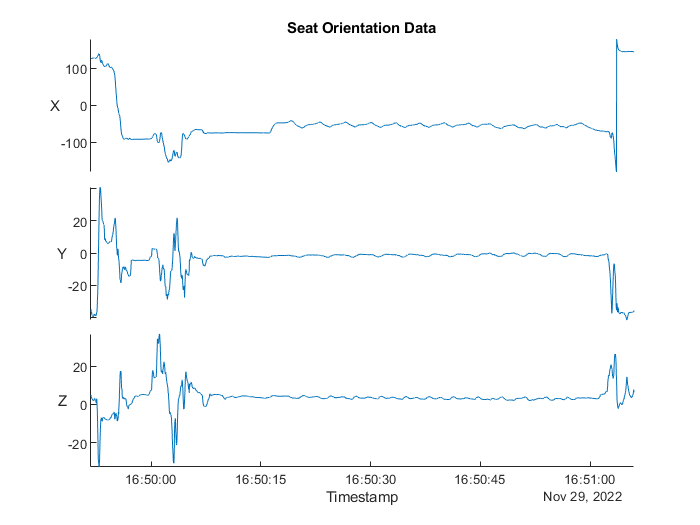


clf;
stackedplot(seat.Orientation);
title("Seat Orientation Data")

% handle x orientation seems to be off by about -80 degrees
%handle.Orientation(:,1) = handle.Orientation(:,1) + -79.1425;

rotated_data = [];
rotated_orientation = [];

tx = 0;
ty = -2;
tz = 0;

quat = quaternion([tx,ty,tz],'eulerd','XYZ','frame');
rotated_data = rotateframe(quat, handle.Acceleration{:, 1:3});

% for i = 1985:3000
%     acc_point = handle.Acceleration{i,:};
%     or_point = handle.Orientation{i,:};
%     
%     tx = -or_point(1)-79.14;
%     ty = -or_point(2);
%     tz = -or_point(3);
%     
%     quat = quaternion([tx,ty,tz],'eulerd','XYZ','frame');
%     new_acc_point = rotateframe(quat, acc_point);
%     new_or_point = rotateframe(quat, or_point);
%     
%     rotated_data(i-1984, :) = new_acc_point;
%     rotated_orientation(i-1984, :) = new_or_point;
% end

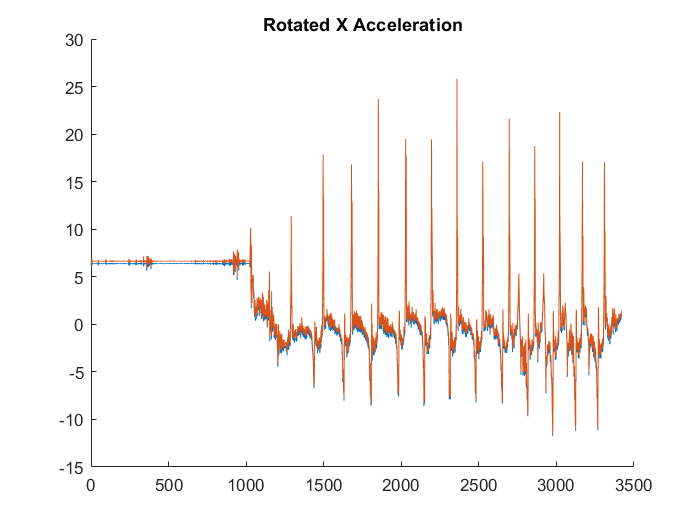

% plotting rotated data
clf; hold on;
plot(1:3420, handle.Acceleration{:,1})
plot(1:3420,rotated_data(:,1));
title("Rotated X Acceleration")

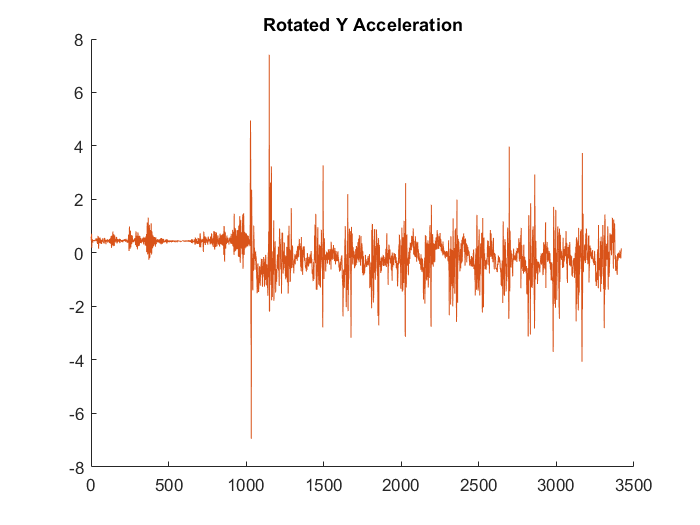


clf; hold on;
plot(1:3420, handle.Acceleration{:,2})
plot(1:3420,rotated_data(:,2));
title("Rotated Y Acceleration")

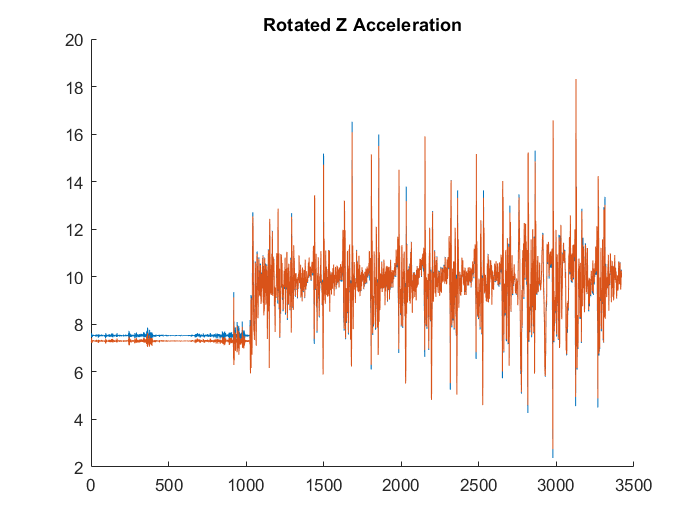


clf; hold on;
plot(1:3420, handle.Acceleration{:,3})
plot(1:3420,rotated_data(:,3));
title("Rotated Z Acceleration")



% plotting rotated orientation data for a test
% clf; hold on;
% plot(1:1016, handle.Orientation{1985:3000,1})
% plot(1:1016,rotated_orientation(:,1));
% title("Rotated X Orientation")
% 
% clf; hold on;
% plot(1:1016, handle.Orientation{1985:3000,2})
% plot(1:1016,rotated_orientation(:,2));
% title("Rotated Y Orientation")
% 
% clf; hold on;
% plot(1:1016, handle.Orientation{1985:3000,3})
% plot(1:1016,rotated_orientation(:,3));
% title("Rotated Z Orientation")